# zad 1

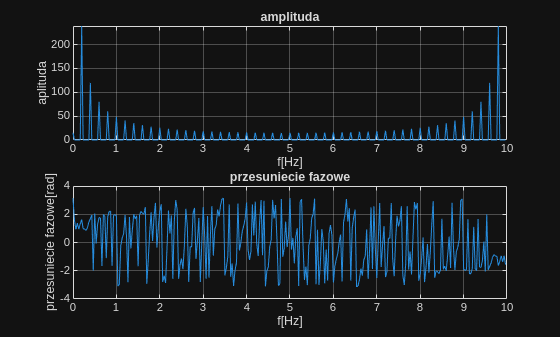

close all
x = load("Sawtooth_weve.dat");

x_trans=fft(x);
ck = x_trans;

f1=(1:length(x))*(10/length(x));

%ak=abs(ck) bk=-2Re{ck}

plotspectrum(x,10);

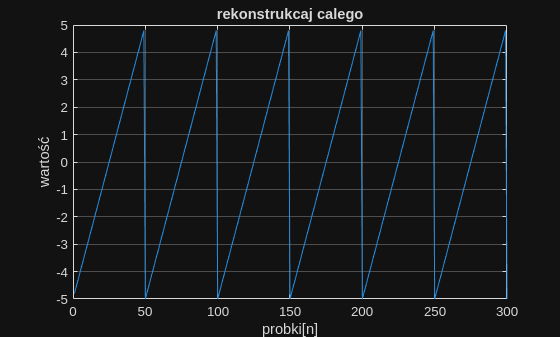

len = length(x_trans);

ck_abs=abs(ck);
ck_fi=angle(ck);

figure 
plot(fftrecon(ck_abs,ck_fi,len))
title("rekonstrukcaj calego")
grid on
xlabel("probki[n]")
ylabel("wartość")

## i reprezentuje ilosc wzietych pod uwage harmonicznych przy odzyskaniu sygnału

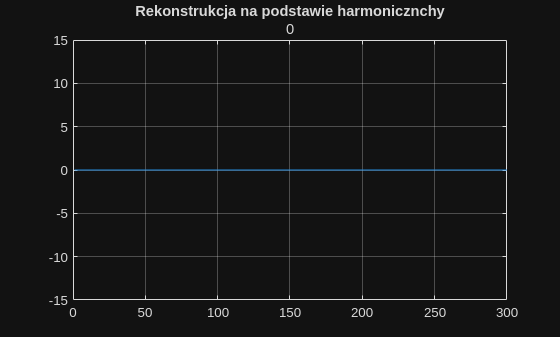

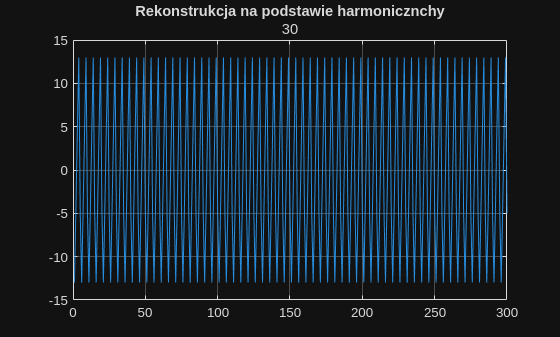

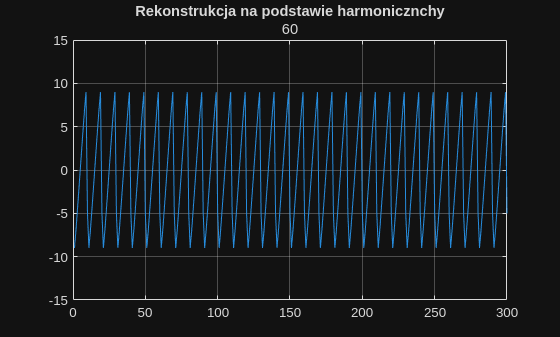

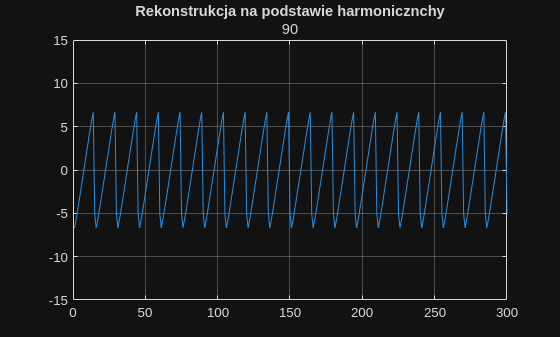

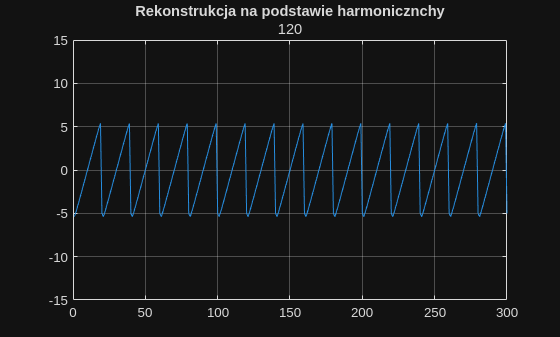

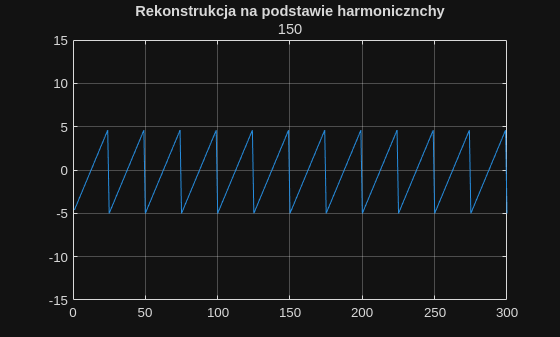

for i=0:30:150
figure 
plot(fftrecon(ck_abs,ck_fi,i))
title("Rekonstrukcja na podstawie harmonicznchy",i)
grid on
xlim([0 300])
ylim([-15.0 15.0])
end

widać ze dla 150 harmonicznych nasz sygnał zaczyna byc dobrze rekonstruowany natomiast dla mniejszej losci nie zgadzaja sie czestotliwosci i amplitudy

## zad 2

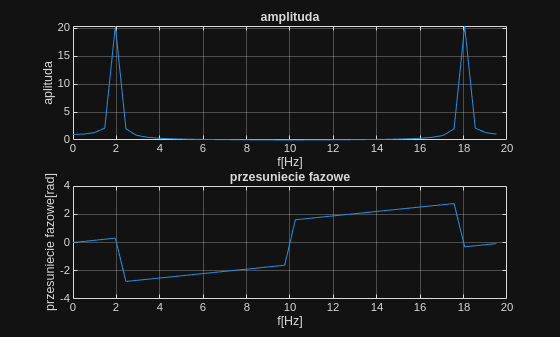

Ts=1/20;
t=0:Ts:2;

signal = cos(4*pi*t);

plotspectrum(signal,20);

## przesuniecia fazowe

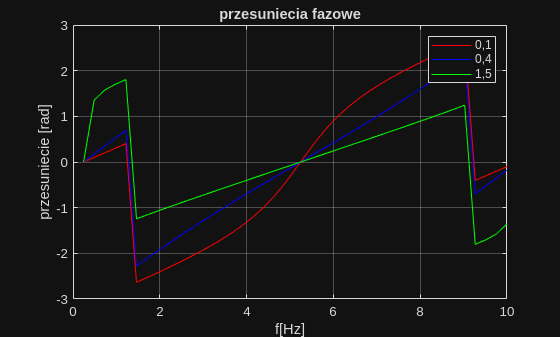

signal1 = cos(4*pi*t+0.1);
signal2 = cos(4*pi*t+ 0.4);
signal3 = cos(4*pi*t+ 1.5);

sig1_t=fft(signal1);
sig2_t=fft(signal2);
sig3_t=fft(signal3);

f2=(1:length(signal1))*(10/length(signal1));

figure
plot(f2,angle(sig1_t),"Color","red")
hold on
plot(f2,angle(sig2_t),"Color","blue")
hold on 
plot(f2,angle(sig3_t),"Color","green")
hold off
legend("0,1","0,4","1,5")
title("przesuniecia fazowe")
xlabel("f[Hz]")
ylabel("przesuniecie [rad]")
grid on 

## zmiana czestotliwosci

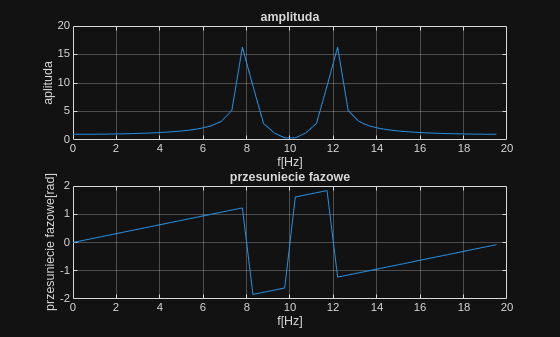

sig_f=cos(24*pi*t);
sig_f_t=fft(sig_f);

plotspectrum(sig_f,20);

## Okna czasowe 

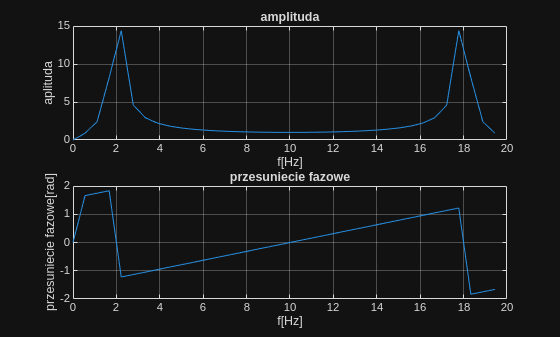

t=0:1/20:1.75;
sig=cos(4*pi*t);
sig_t=fft(sig);

window_rect=ones(1,length(t));
window_hann=hann(length(t));
window_hamm=hamming(length(t));

[f3,amp,arg]=plotspectrum(sig,20);

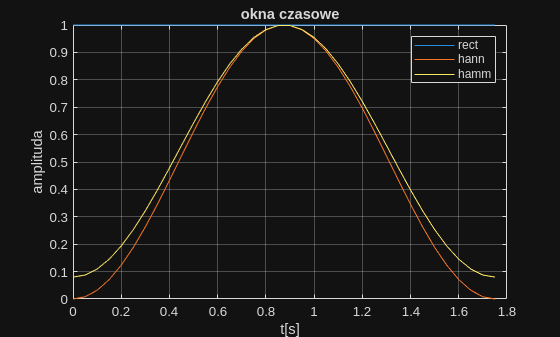

figure 
plot(t, window_rect);
hold on;
plot(t, window_hann);
hold on 
plot(t, window_hamm);
title('okna czasowe');
xlabel('t[s]');
ylabel('amplituda');
legend('rect', 'hann', 'hamm');
grid on;

Jak widac na wykresie okno prostokątne nie wpływa na sygnał w żaden sposób natomias okno Hanna i Hamminga wypłaszczaja graniczne wartości 

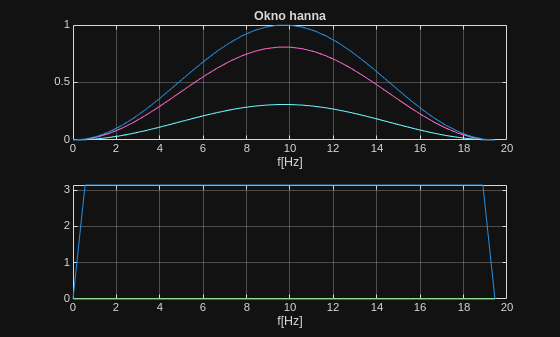

sig_hann=sig.*window_hann;
sig_hamm=sig.* window_hamm;

figure
subplot(2,1,1)
plot(f3,abs(sig_hann))
title("Okno hanna")
xlabel("f[Hz]")
grid on

subplot(2,1,2)
plot(f3,angle(sig_hann))
xlabel("f[Hz]")
grid on 

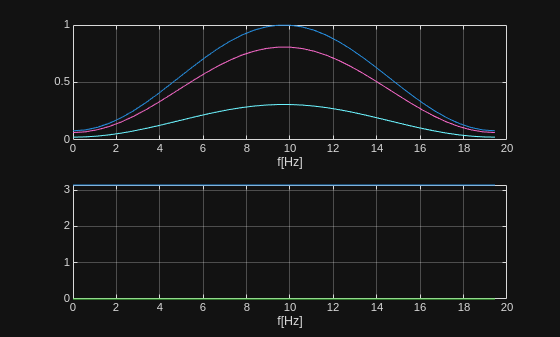


figure
subplot(2,1,1)
plot(f3,abs(sig_hamm))
xlabel("f[Hz]")
grid on

subplot(2,1,2)
plot(f3,angle(sig_hamm))
xlabel("f[Hz]")
grid on 